clear all;

## Onset Conditions

dimension:

N=1500;
% correlation paramter:
eta=0;% 1 is symmetric
% amplitude
JAmp=1;
% Sparsity of J
Mdensity=0;
% Tot time 
tot_time=5000;
% Delta t:
Dt=0.1;
% Temperature: Increase it!!!
T=0.01;
% Initialise
J=zeros(N,N);
%x=zeros(N,N_tot);
% ICs
var_ICs_X=0.01;
x(:,1)=var_ICs_X*randn(N,1);
M=sum(x(:,1).^2);
% Fix the constraint sum x^2=N for all t
x(:,1)=x(:,1)*sqrt(N)/sqrt(M);

## Generate Random Matrix:

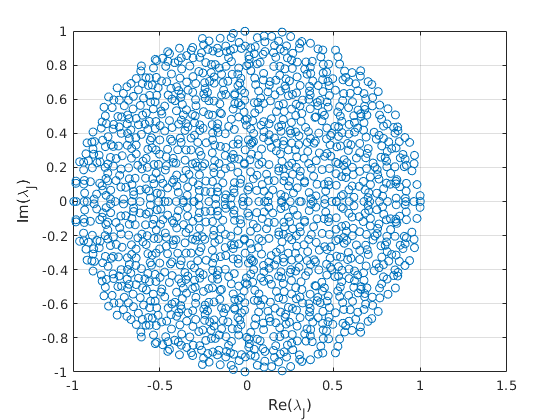

if eta==0
    J=JAmp/sqrt(N)*randn(N);   
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
J=J-diag(diag(J));
else
    a=sqrt(1-eta^2);
    a=sqrt((1-a)/2);
    b=eta/(2*a);    
    J=JAmp/sqrt(N)*randn(N);    
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
    J=a*J+b*J';
    J=J-diag(diag(J));
end;
figure;
plot(real(eig(J)),imag(eig(J)),'o');hold on;grid on;
xlabel('Re(\lambda_J)');
ylabel('Im(\lambda_J)')

%hold on;

## Run Dynamics

doin the for loop here appears to be slower, it is faster to run a simulation in a separate function

N_iter=tot_time/Dt;
tic
for i=2:N_iter
        z=randn(N,1)*sqrt(2*Dt*T);
        f=Dt*J*x(:,i-1)+z;
        x_norm=norm(x(:,i-1))^2;
        %x_norm=N;
        xf=x(:,i-1)'*f;
        x(:,i)=x(:,i-1)*(-xf/x_norm+sqrt((xf/x_norm)^2+(N-norm(f)^2)/x_norm))+f;
end
toc

Elapsed time is 292.052368 seconds.



x=steps(x(:,1),1,1000,Dt,N,J,0,100);

Elapsed time is 13.863427 seconds.


save('low_T_unperturbed','x','J','T','Dt','tot_time');

load('low_T_unperturbed.mat')

## Perturned Dynamics   $ $\frac{x_{per}-x_{unp}}{h}=\int_0^{t} dt' G(t')$$

clear per
clear unper
clear mean_chi
clear std_chi
rng(10);
t=[0.01 0.2 0.4 0.6 0.8 1 1.2 1.4 1.6]

t =          0.01          0.2          0.4          0.6          0.8            1          1.2          1.4          1.6


h=.1;
for i=1:length(t)
    rng(10);
    unper=mean(steps(x(:,1),t(i),70,Dt/10,N,J,0,10));
    rng(10);
    per=mean(steps(x(:,1),t(i),70,Dt/10,N,J,h,10));
    mean_chi(i)=mean(per-unper)/h;
    std_chi(i)=std(per-unper)/h;
end

Elapsed time is 10.105464 seconds.


Elapsed time is 10.976637 seconds.


Elapsed time is 11.198530 seconds.


Elapsed time is 11.063206 seconds.


Elapsed time is 10.144766 seconds.


Elapsed time is 10.016707 seconds.


Elapsed time is 9.790464 seconds.


Elapsed time is 10.590025 seconds.


Elapsed time is 12.590954 seconds.


Elapsed time is 14.507757 seconds.


Elapsed time is 11.829043 seconds.


Elapsed time is 11.798160 seconds.


Elapsed time is 13.824171 seconds.


Elapsed time is 13.301683 seconds.


Elapsed time is 14.143150 seconds.


Elapsed time is 14.619074 seconds.


Elapsed time is 12.719109 seconds.


Elapsed time is 11.547813 seconds.


figure()
errorbar(t,mean_chi,std_chi,'o','DisplayName','Simulation')
xlabel('T','FontSize',18)
ylabel('\chi','FontSize',18)
hold on
plot((0:0.1:1.6),(1+(0:0.1:1.6).^2).^-0.5,'DisplayName','Theory')
hold off
l=legend('show');
l.FontSize=18

l =   Legend (Simulation, Theory) with properties:

         String: {'Simulation'  'Theory'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 18
       Position: [0.5619 0.74563 0.31964 0.14881]
          Units: 'normalized'

  Show all properties


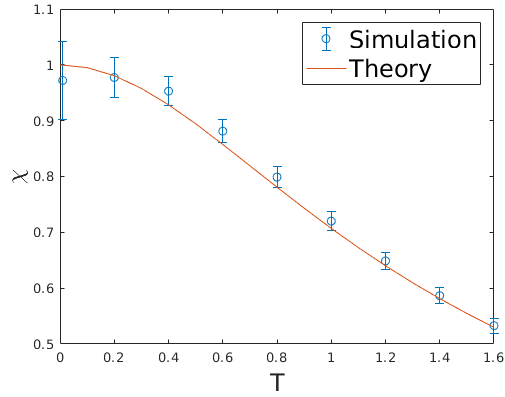

ans =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [403 246 505.33 396.8]
       Units: 'pixels'

  Show all properties


tightfig()

rng(2)
unper=mean(steps(x(:,1),0.01,700,Dt,N,J,0,2000));

Elapsed time is 36.018847 seconds.


rng(2);
per=mean(steps(x(:,1),.01,700,Dt,N,J,0.01,2000));

Elapsed time is 36.131981 seconds.


mean_chi(1)=mean(per-unper)/.01;
std_chi(1)=std(per-unper)/.01;

save ('chi_asy.mat','mean_chi','std_chi','t')

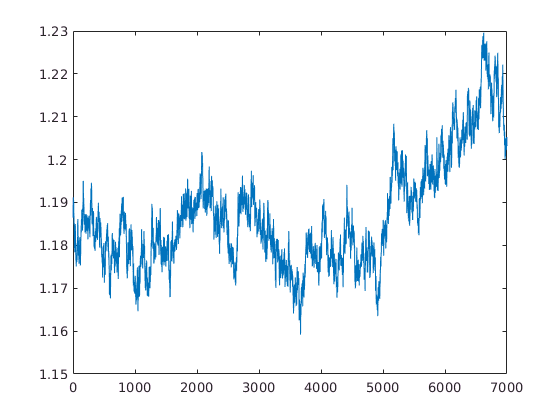

plot((per-unper)/0.01)

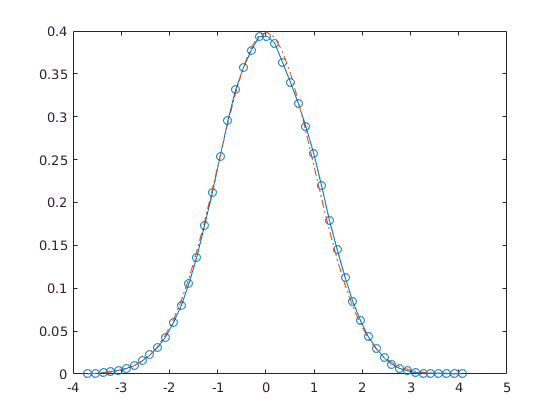

figure()
%histogram of position for one spin
bin_edge=linspace(min(x(:)),max(x(:)),50);
H=0;
for i=1:size(x,1)
    [h,b]=histcounts(x(:,i),bin_edge);
    H=H+h;
end
normalisation=sum(H)*(bin_edge(2)-bin_edge(1));
plot((bin_edge(1:end-1)+bin_edge(2:end))/2,H/normalisation,'-o')
hold on
spins=(bin_edge(1:end-1)+bin_edge(2:end))/2;
prob=exp(-spins.^2/2);
plot(spins,prob/sum(prob)/(bin_edge(2)-bin_edge(1)),'-.')

x=steps(x(:,1),.01,6000,Dt,N,J,0,1000);

Elapsed time is 101.131185 seconds.


I compute  $\langle x_t x_{t'}\rangle=\frac{1}{N}\sum_{i=1}^N x_{i,t}x_{i,t'}$ i.e. I average over the different realisation of the spins.

[mean_corr,std_corr]=correlation(x,1,Dt,inf);

Plot the correlation function

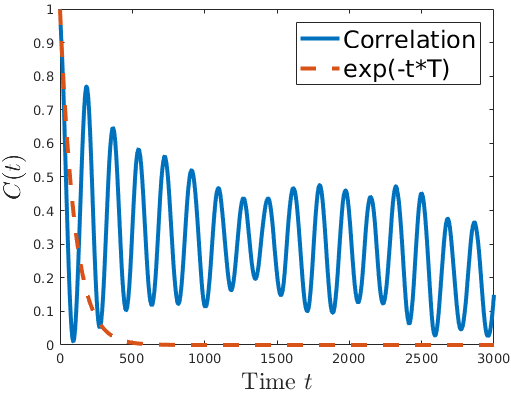

figure()
plot((1:length(mean_corr))*Dt,mean_corr,'LineWidth',3,'DisplayName','Correlation')
%xlim([10,400]);
%ylim([-0.5,0.5])
hold on
t=(1:length(mean_corr))*Dt;
plot(t,exp(-t*0.01),'--','LineWidth',3,'DisplayName','exp(-t*T)')
%f=fill([(1:length(mean_corr))*Dt fliplr((1:length(mean_corr))*Dt)],[mean_corr-std_corr/sqrt(N)  fliplr(mean_corr+std_corr/sqrt(N))],'g','DisplayName','Std. deviation');
%set(f,'facealpha',.25)
hold off
lg=legend('show')
lg.FontSize=18;
xlabel('Time $t$','Interpreter','latex','FontSize',18)
ylabel('$C(t)$','Interpreter','latex','FontSize',18)
tightfig()
hold off

plot((1:length(cov))*Dt,cov)
% Fourier transfrorm of correlation function
P2=abs(fft(corr));
P1=P2(1:(end+1)/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = 1/Dt*linspace(0,0.5,N_iter);
plot(f,P1(1:end-2))

q vs temperature

clear q
clear err_q
for i=1:9   
    trajectory=steps(x(:,1),0.1*i,1000,Dt,N,J,0);
    [mean_corr,std_corr]=correlation(trajectory,100,Dt,inf);
    q(i)=mean(mean_corr(100/Dt:end));
    err_q(i)=mean(std_corr(100/Dt:end));
end

Elapsed time is 160.287417 seconds.
Elapsed time is 188.887570 seconds.
Elapsed time is 172.980601 seconds.
Elapsed time is 167.107472 seconds.
Elapsed time is 160.975304 seconds.
Elapsed time is 160.591566 seconds.
Elapsed time is 149.470480 seconds.
Elapsed time is 172.112022 seconds.
Elapsed time is 136.524217 seconds.


save('q.mat','q','err_q')

figure()
%plot the q relation 
errorbar(0.1*(1:9),q,err_q/sqrt(N),'*','MarkerSize',12,'MarkerEdgeColor','red','MarkerFaceColor','red','DisplayName','q')
 hold on
 plot(0:1,1-(0:1),'m--','LineWidth',1,'DisplayName','1-T','Color',[0.4940, 0.1840, 0.5560])
 hold off
 xlabel('T','FontSize',18);
 ylabel('q','FontSize',18);
lg=legend('show')

lg =   Legend (q, 1-T) with properties:

         String: {'q'  '1-T'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.75476 0.8123 0.12679 0.082143]
          Units: 'normalized'

  Show all properties


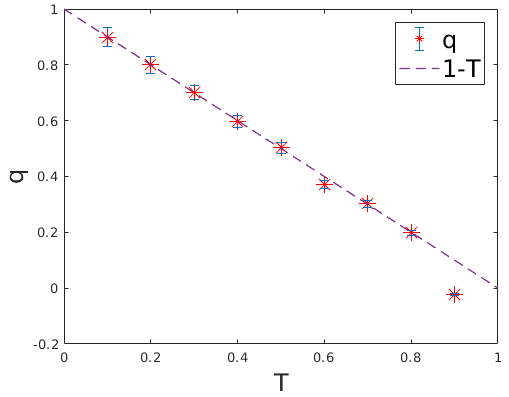

ans =   Figure (52) with properties:

      Number: 52
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [403 246 509.33 396.8]
       Units: 'pixels'

  Show all properties


lg.FontSize=18;
tightfig()

%Integrated response function
load('perturbed_low_T.mat')
pert=x;
clear x
load('low_T.mat');
unpert=x;

mean((mean(pert))-mean(mean(unpert)))./0.001